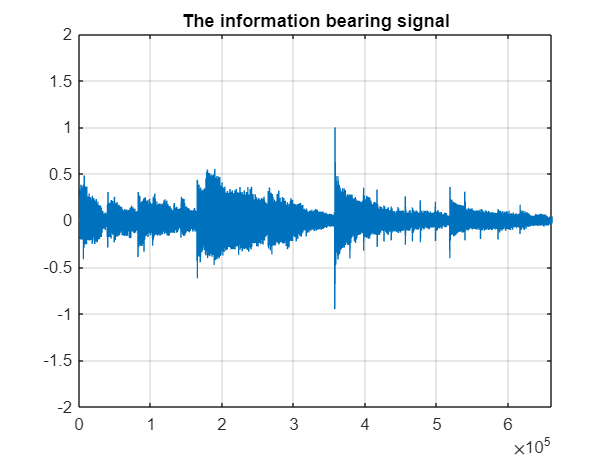

% signal = sin(2*pi*0.055*(0:1000-1)');
% signalSource = dsp.SignalSource(signal,'SamplesPerFrame',100,...
%     'SignalEndAction','Cyclic repetition');

[s, Fs] = audioread('guitartune.wav');
plot(0:length(s)-1,s);
grid; axis([0 length(s)-1 -2 2]);
title('The information bearing signal');

% nvar  = 1.0;                  % Noise variance
% noise = randn(1000,1)*nvar;   % White noise
% noiseSource = dsp.SignalSource(noise,'SamplesPerFrame',100,...
%     'SignalEndAction','Cyclic repetition');
% plot(0:999,noise);
% title('Noise picked up by the secondary microphone');
% grid; axis([0 1000 -4 4]);

rand_noise = randn(size(s));
r = sqrt(var)*rand_noise; 

lp = dsp.FIRFilter('Numerator',fir1(31,0.5));% Low pass FIR filter

M      = 32;                 % Filter order
delta  = 0.1;                % Initial input covariance estimate
P0     = (1/delta)*eye(M,M); % Initial setting for the P matrix
rlsfilt = dsp.RLSFilter(M,'InitialInverseCovariance',P0);

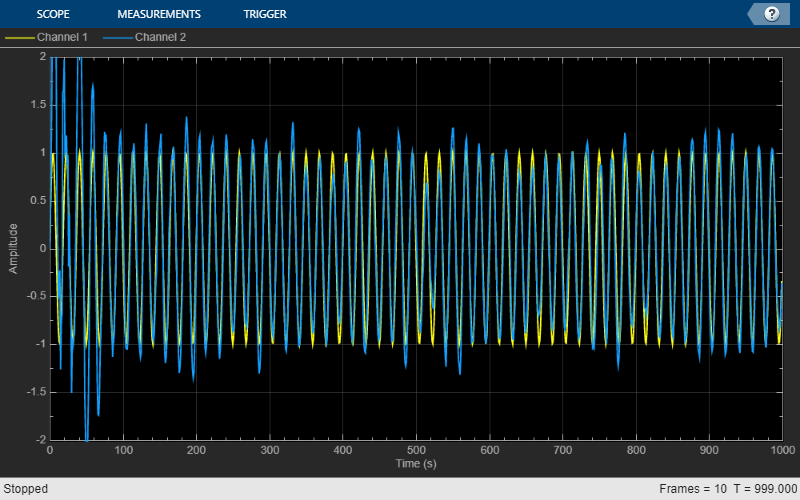

scope = timescope('TimeSpan',1000,'YLimits',[-2,2], ...
	                  'TimeSpanOverrunAction','Scroll');
for k = 1:10
    n = noiseSource(); % Noise
    s = signalSource();
    d = lp(n) + s;
    [y,e]  = rlsfilt(n,d);
    scope([s,e]);
end
release(scope);

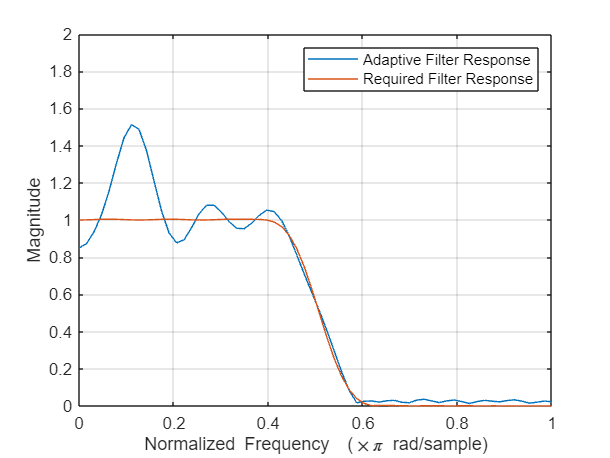

H  = abs(freqz(rlsfilt.Coefficients,1,64));
H1 = abs(freqz(lp.Numerator,1,64));

wf = linspace(0,1,64);

plot(wf,H,wf,H1);
xlabel('Normalized Frequency  (\times\pi rad/sample)');
ylabel('Magnitude');
legend('Adaptive Filter Response','Required Filter Response');
grid;
axis([0 1 0 2]);

sound(y,Fs)